QPO accessibility and fixed-target UV pipeline

Configure the first section, then run the script. Helper functions are in the functions folder.

RUN_QPO_Accessibility_FixedTargetUV

% QPO collector-triangle accessibility and fixed-target UV coverage.
% Run this script/livescript after placing this folder near your GMOS Code folder.
%
% Architecture:
%   - Beam combiner follows the parent periodic orbit.
%   - Three collectors are selected as equally spaced samples on one corrected
%     GMOS QPO invariant curve.
%   - The three collectors define an instantaneous triangle plane and normal.
%   - Accessibility is computed by comparing the triangle normal with a target
%     direction expressed in the CR3BP rotating frame at each time.
%   - Fixed-target UV coverage is computed in the conventional astrophysical
%     way: choose one target direction first, define a target-centered sky
%     basis, transform baselines consistently, then project baselines into the
%     fixed target sky plane.
%
% Important conventions:
%   1) Synodic/rotating CR3BP coordinates are the propagation coordinates.
%   2) The synodic +z axis is also the inertial +z axis.
%   3) Direction transform used here:
%          q_I(t) = R3(t) q_S(t),
%      where R3(t) is a positive rotation about +z by nondimensional CR3BP
%      time t. If your CR3BP-to-inertial convention uses the opposite sign,
%      flip the sign in rotate_synodic_to_inertial_rows and
%      rotate_inertial_to_synodic_rows.
%   4) For a physically fixed star, use targetFrame = 'inertial'.
%   5) For a CR3BP-relative pointing direction, use targetFrame = 'synodic'.
%      That is useful for dynamics, but it is not a fixed celestial source.

clear; clc; close all;

thisPipelineDir = fileparts(mfilename('fullpath'));
addpath(fullfile(thisPipelineDir, 'functions'));

User configuration


thisDir = thisPipelineDir;
if isfolder(fullfile(thisDir, 'Code'))
    codeDir = fullfile(thisDir, 'Code');
elseif isfolder(fullfile(thisDir, '..', 'Code'))
    codeDir = fullfile(thisDir, '..', 'Code');
elseif isfolder(fullfile(thisDir, 'Code_GMOS', 'Code'))
    codeDir = fullfile(thisDir, 'Code_GMOS', 'Code');
elseif isfolder(fullfile(thisDir, '..', 'Code_GMOS', 'Code'))
    codeDir = fullfile(thisDir, '..', 'Code_GMOS', 'Code');
else
    codeDir = thisDir;
    warning('Could not automatically find your GMOS Code folder. Add it to the MATLAB path manually if needed.');
end

addpath(codeDir);

% CR3BP system. This default matches your Earth-Moon examples.
mu = 1.215058560962404e-2;

% Parent periodic orbit for the beam combiner.
poFile = 'L1_northern_halo_orbits_JPL_IC_Earth_Moon.csv';
orbitIndex = 200;

% Corrected GMOS QPO family for the collectors.
qpoFamilyFile = 'fam_fixT_halo.mat';
qpoFamilyVariable = 'fam';
qpoIndex = [];              % [] means use the last family member

% GMOS curve discretization used in the correction.
N = 51;

% Three collectors define the minimum physical array plane.
nCollectors = 3;
phaseStartIndex = 5;        % arbitrary absolute phase origin on XCurve columns

% Propagation length.
nPrimaryPeriods = 1;
nSavePerPrimaryPeriod = 600;

% UV units.
% For geometry/debug, leave lengthScale = 1 and lambda = 1.
% For physical UV in wavelengths, use dimensional lengthScale and lambda.
% Example Earth-Moon: lengthScale = 384400e3; lambda = 10e-6;
lengthScale = 1.0;
lambda = 1.0;

% Normal sign convention. The plane has n and -n ambiguity. We enforce sign
% continuity and then align the first normal with this reference if nonempty.
normalReferenceSynodic = [0, 0, 1];

% Fixed-target definition.
%   targetFrame = 'inertial': physically fixed celestial target.
%   targetFrame = 'synodic' : CR3BP-corotating target direction.
targetFrame = 'inertial';

% Use either a vector or RA/Dec. The vector option is the least ambiguous in
% the CR3BP reference system.
useRaDec = true;
raDeg = 0.0;
decDeg = 60.0;

% If useRaDec = false and targetFrame = 'inertial', this is a fixed inertial
% direction expressed in the inertial CR3BP basis at t = 0.
sTargetInertial = normalize_row([1.0, 0.35, 0.20]);

% If useRaDec = false and targetFrame = 'synodic', this is a fixed direction
% in the rotating CR3BP basis.
sTargetSynodic = normalize_row([1.0, 0.0, 0.20]);

% Accessibility half-angle. Since the collector plane has +/- normal
% ambiguity, the default uses abs(dot(n, s)).
maxOffNormalDeg = 20.0;
usePlaneNormalSignAmbiguity = true;

% Sky-basis reference axis. For an inertial target, this is normally +z,
% which gives v approximately north/ecliptic-north and u east-like. If the
% target is near +z, the code falls back automatically.
skyNorthReference = [0, 0, 1];

% Numerical tolerances.
odeOpts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

% Saving.
saveResults = true;
saveFigures =true;
figDir = fullfile(pwd, 'qpo_accessibility_uv_figs');

Plot defaults


set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');
set(groot, 'DefaultAxesFontSize', 18);
set(groot, 'DefaultTextFontSize', 20);
set(groot, 'DefaultLineLineWidth', 1.4);

Load parent periodic orbit and corrected QPO


po = pick_po_from_JPL(poFile, orbitIndex);
xCombiner0 = po.x0(:);
TPrimary = po.T;

S = load(qpoFamilyFile);
if isfield(S, qpoFamilyVariable)
    fam = S.(qpoFamilyVariable);
else
    names = fieldnames(S);
    if numel(names) ~= 1
        error('Could not infer family variable. Set qpoFamilyVariable explicitly.');
    end
    fam = S.(names{1});
end

zQPO = get_family_member_z(fam, qpoIndex);

% Allow for continuation vectors of the form [z; mu]. If present, strip mu.
if numel(zQPO) == 6*N + 3
    fprintf('Detected [z; mu] vector. Using mu from vector end.\n');
    mu = zQPO(end);
    zQPO = zQPO(1:end-1);
end

[XCurve, TQPO, rhoQPO] = gmos_unpack_z(zQPO, N);

fprintf('\nParent periodic orbit\n');


Parent periodic orbit


fprintf('  orbit index = %d\n', orbitIndex);

  orbit index = 200


fprintf('  TPrimary    = %.16e\n', TPrimary);

  TPrimary    = 1.9494988463649532e+00


fprintf('\nQPO member\n');


QPO member


fprintf('  TQPO        = %.16e\n', TQPO);

  TQPO        = 1.9494988463649532e+00


fprintf('  rhoQPO      = %.16e rad\n', rhoQPO);

  rhoQPO      = 6.5056291998387550e-01 rad


fprintf('  rhoQPO/2pi  = %.16e cycles\n', rhoQPO/(2*pi));

  rhoQPO/2pi  = 1.0354030450773097e-01 cycles


fprintf('  |TQPO - TPrimary|/TPrimary = %.3e\n', abs(TQPO - TPrimary)/TPrimary);

  |TQPO - TPrimary|/TPrimary = 0.000e+00


Select arbitrary equal-phase 3-collector triangle


jCollectors = qpo_equal_phase_indices(N, nCollectors, phaseStartIndex);
XCollectors0 = XCurve(:, jCollectors);

fprintf('\nCollector QPO curve indices\n');


Collector QPO curve indices


fprintf('  phaseStartIndex = %d\n', phaseStartIndex);

  phaseStartIndex = 5


fprintf('  jCollectors     = [%d, %d, %d]\n', jCollectors(1), jCollectors(2), jCollectors(3));

  jCollectors     = [5, 22, 39]


fprintf('  phase fractions = [%.6f, %.6f, %.6f]\n', ...
    (jCollectors(1)-1)/N, (jCollectors(2)-1)/N, (jCollectors(3)-1)/N);

  phase fractions = [0.078431, 0.411765, 0.745098]


Propagate and compute geometry


geom = compute_three_collector_qpo_geometry( ...
    mu, xCombiner0, TPrimary, XCollectors0, ...
    nPrimaryPeriods, nSavePerPrimaryPeriod, odeOpts, normalReferenceSynodic);

geom.config.mu = mu;
geom.config.N = N;
geom.config.poFile = poFile;
geom.config.orbitIndex = orbitIndex;
geom.config.TPrimary = TPrimary;
geom.config.TQPO = TQPO;
geom.config.rhoQPO = rhoQPO;
geom.config.qpoFamilyFile = qpoFamilyFile;
geom.config.qpoFamilyVariable = qpoFamilyVariable;
geom.config.qpoIndex = qpoIndex;
geom.config.jCollectors = jCollectors;
geom.config.phaseStartIndex = phaseStartIndex;
geom.config.lengthScale = lengthScale;
geom.config.lambda = lambda;
geom.config.normalReferenceSynodic = normalReferenceSynodic;

Define target, compute accessibility, and compute fixed-target UV


target = make_target_definition( ...
    targetFrame, useRaDec, raDeg, decDeg, sTargetInertial, sTargetSynodic, ...
    skyNorthReference);

access = compute_triangle_accessibility( ...
    geom, target, maxOffNormalDeg, usePlaneNormalSignAmbiguity);

uvFixed = compute_fixed_target_uv(geom, target, lengthScale, lambda);

print_geometry_accessibility_uv_summary(geom, access, uvFixed);


Three-collector QPO geometry summary
  time span = 1.000 primary periods

Collector-collector baseline ranges
  L12: [1.634045e-02, 1.038339e-01]
  L13: [1.614589e-02, 4.445265e-02]
  L23: [1.290411e-02, 8.480471e-02]

Combiner-centroid offset
  ||centroid - combiner|| min/mean/max = 7.871496e-04 / 2.922472e-03 / 1.907422e-02
  normalized offset min/mean/max = 6.811800e-02 / 1.099933e-01 / 4.283836e-01

Triangle area and normal conditioning
  area min/mean/max = 8.151125e-05 / 2.718695e-04 / 5.917858e-04
  sin(angle b12,b13) min/mean/max = 4.594028e-02 / 6.634532e-01 / 9.999994e-01
  degenerate samples = 0 of 601

Target accessibility
  max off-normal angle = 20.000 deg
  off-normal angle min/mean/max = 17.059469 / 56.820974 / 89.546629 deg
  accessible fraction = 4.83 %

Fixed-target UV coverage summary
  frame = fixed inertial target sky basis
  units = baseline/lambda, lengthScale/lambda = 1.000000e+00
  rho12 min/mean/max = 1.505505e-02 / 3.331362e-02 / 1.034177e-01
  rho13 min/me

Plots

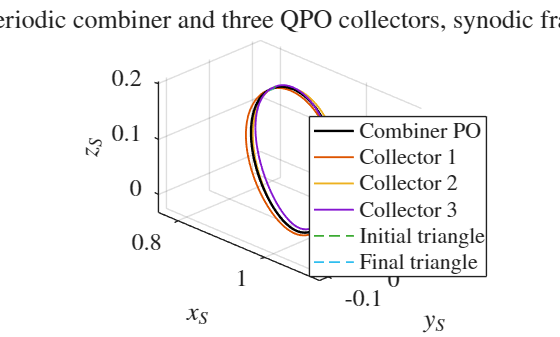

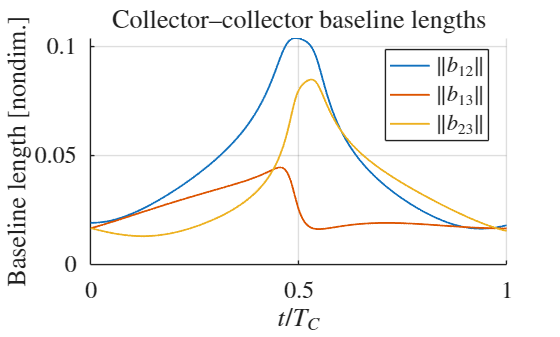

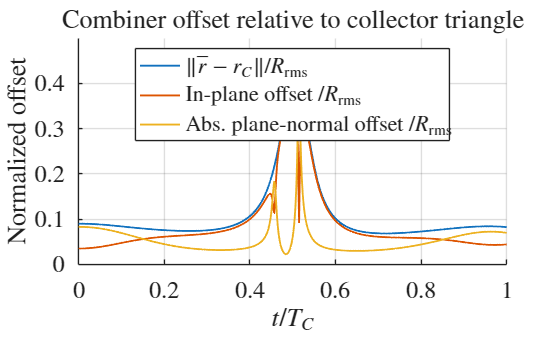

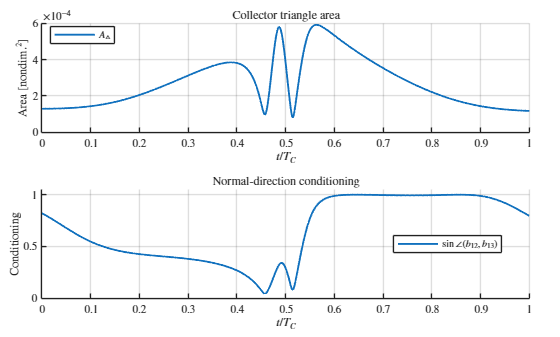

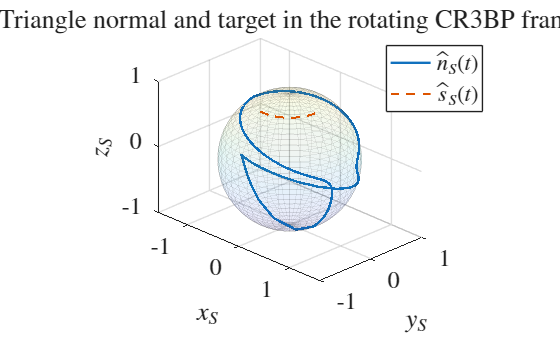

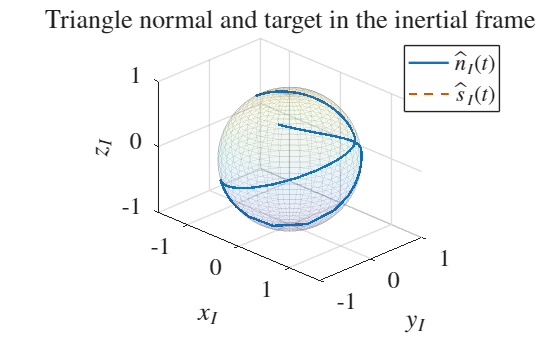

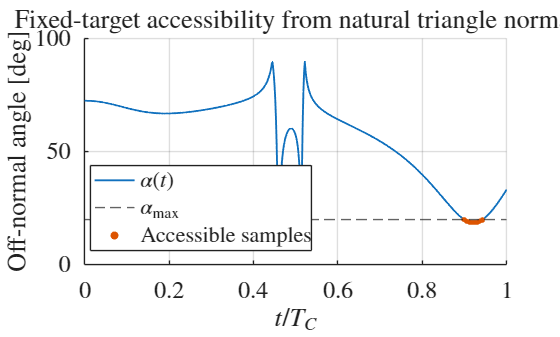

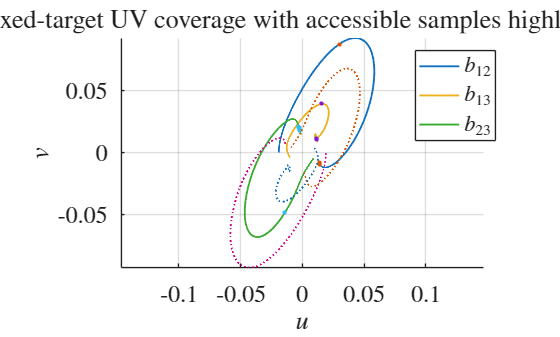


figs = plot_accessibility_and_fixed_target_uv(geom, access, uvFixed);

if saveFigures
    if ~isfolder(figDir)
        mkdir(figDir);
    end
    save_all_figures(figs, figDir);
end


if saveResults
    save('qpo_accessibility_fixed_target_uv_results.mat', 'geom', 'target', 'access', 'uvFixed');
end